# S2 | Señales

## Señales básicas

%Señal discreta
x = [1 2 3]

x =      1     2     3


n = [-1 0 1]

n =     -1     0     1



%Señal continua
syms t
x_1 = t^2

$$x\_1 = t^{2}$$

## Ejercicio 1

syms t 
x = 3*exp(0.4*t)

$$x = 3\,{\mathrm{e}}^{\frac{2\,t}{5}}$$

y = 2*exp(-0.9*t)

$$y = 2\,{\mathrm{e}}^{-\frac{9\,t}{10}}$$

fplot(x,[-2,5])

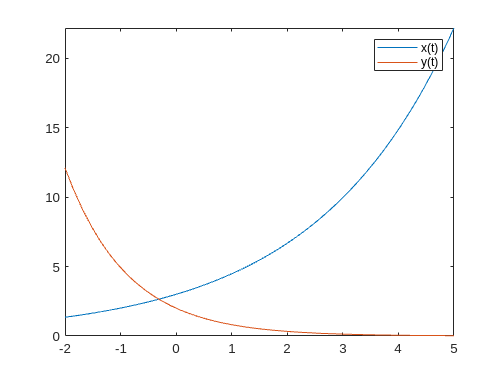

hold on
fplot(y,[-2,5])
hold off
legend("x(t)","y(t)")

## Ejercicio 2

syms t
y = cos(t)

$$y = \cos\left(t\right)$$

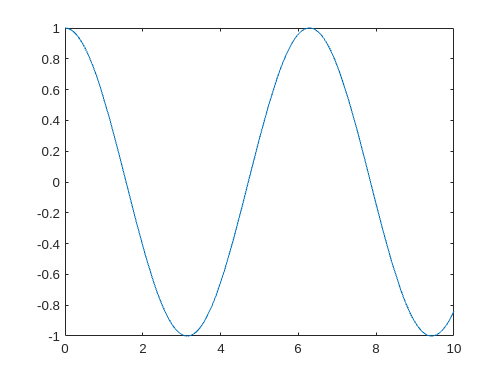

fplot(y,[0 10])


n = [0:10]

n =      0     1     2     3     4     5     6     7     8     9    10


y_1 = cos(n)

y_1 =     1.0000    0.5403   -0.4161   -0.9900   -0.6536    0.2837    0.9602    0.7539   -0.1455   -0.9111   -0.8391


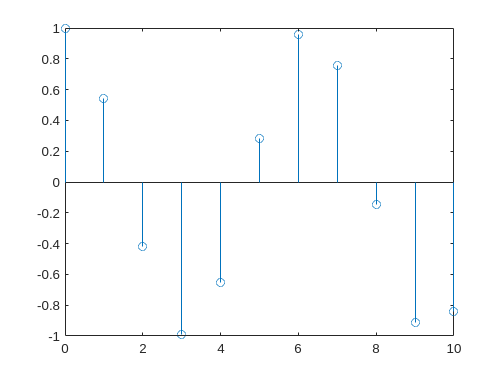

%plot(n,y_1) Se puede
stem(n,y_1)

## Ejercicio 3

syms t
x = cos(t)+sin(3*t)

$$x = \sin\left(3\,t\right)+\cos\left(t\right)$$

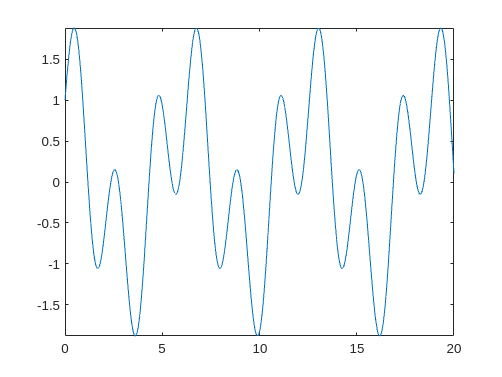

fplot(x,[0 20])

## Ejercicio 4

syms t
x = cos(100*t)*exp(2*t)

$$x = \cos\left(100\,t\right)\,{\mathrm{e}}^{2\,t}$$

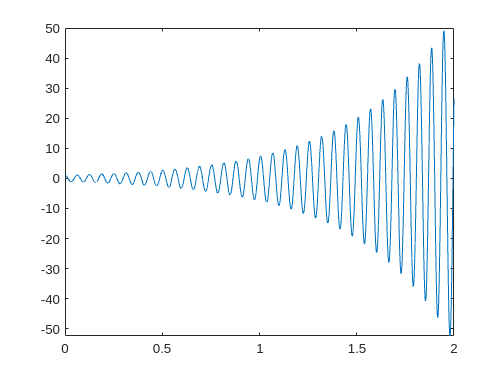

fplot(x,[0 2])

## Ejercicio 5

syms t
y = 2*exp(1j*pi*t+pi/3)

$$y = 2\,{\mathrm{e}}^{\frac{\pi }{3}+\pi \,t\,\mathrm{i}}$$

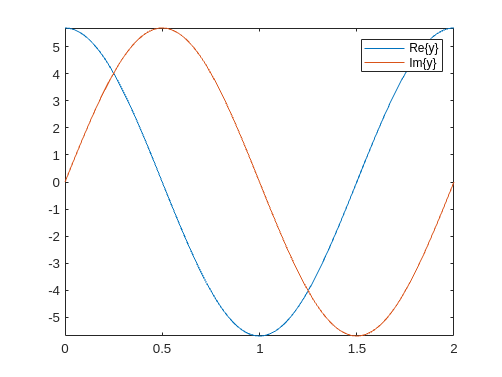


fplot(real(y),[0 2])
hold on
fplot(imag(y),[0 2])
hold off
legend("Re\{y\}","Im\{y\}")

## Función Heaviside

syms t
u = heaviside(t)

$$u = \mathrm{heaviside}\left(t\right)$$

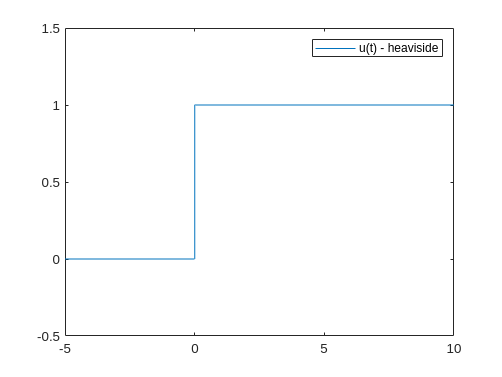

fplot(u,[-5 10])
ylim([-0.5 1.5])
legend("u(t) - heaviside")


heaviside(0)

ans = 0.5000


n = [-5:10]

n =     -5    -4    -3    -2    -1     0     1     2     3     4     5     6     7     8     9    10


u_n = heaviside(n)

u_n =          0         0         0         0         0    0.5000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000


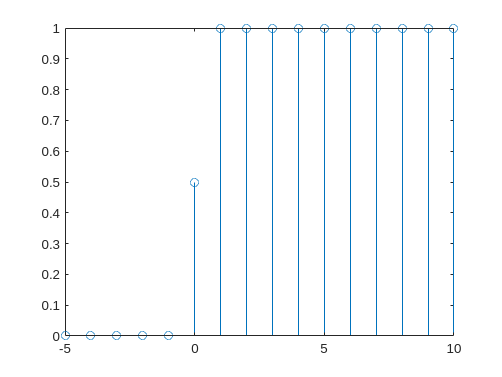

stem(n,u_n)

## Funcion rampa

syms t 
r = t*heaviside(t)

$$r = t\,\mathrm{heaviside}\left(t\right)$$

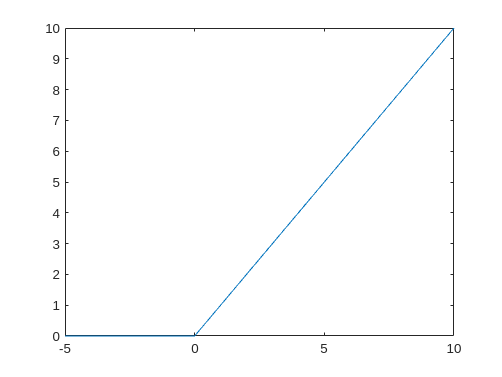


fplot(r,[-5 10])

## Pulso rectangular

syms t
T = 2

T = 2

pT = heaviside(t+T/2)-heaviside(t-T/2)

$$pT = \mathrm{heaviside}\left(t+1\right)-\mathrm{heaviside}\left(t-1\right)$$

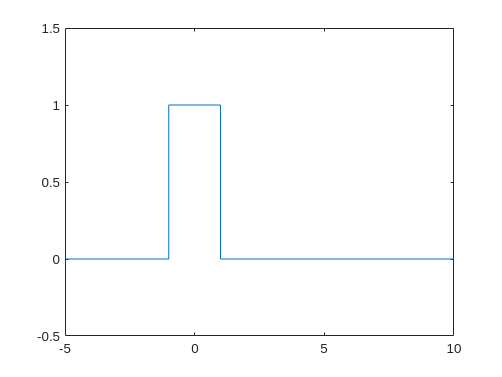

fplot(pT,[-5 10])
ylim([-0.5 1.5])

## Operaciones

syms t
x = t*exp(-t)

$$x = t\,{\mathrm{e}}^{-t}$$

%x = heaviside(t)
ylim_interval = [-3 0.5]

ylim_interval =    -3.0000    0.5000


x_interval = [-3 3]

x_interval =     -3     3


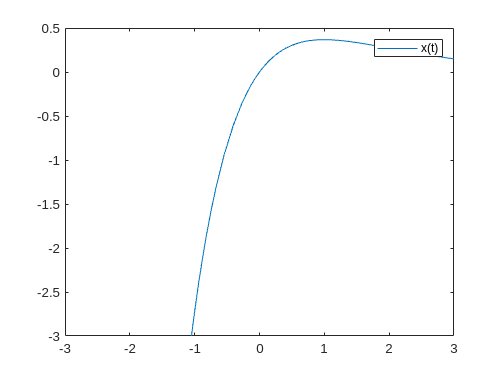


%Original
fplot(x, x_interval)
ylim(ylim_interval)
legend("x(t)")


%Reflejada
x_reflex = subs(x,t,-t)

$$x\_reflex = -t\,{\mathrm{e}}^{t}$$

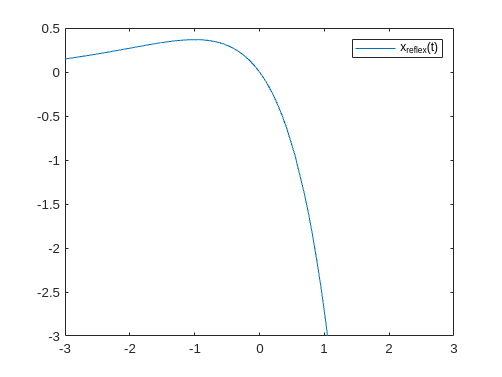

fplot(x_reflex,x_interval)
ylim(ylim_interval)
legend("x_{reflex}(t)")


%Traladada en tiempo
x_tras = subs(x,t,t-2)

$$x\_tras = {\mathrm{e}}^{2-t}\,\left(t-2\right)$$

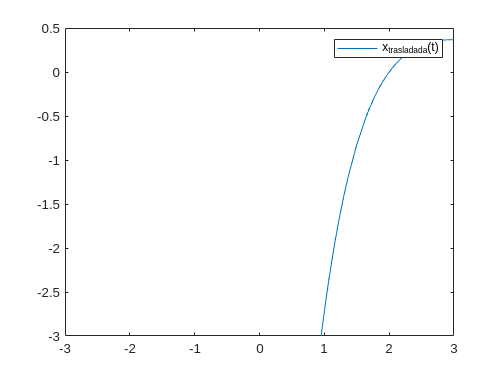

fplot(x_tras,x_interval)
ylim(ylim_interval)
legend("x_{trasladada}(t)")


%Ensanchada en tiempo
x_broad = subs(x,t,t/3)

$$x\_broad = \frac{t\,{\mathrm{e}}^{-\frac{t}{3}}}{3}$$

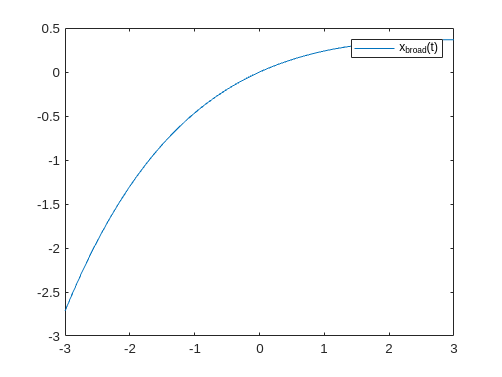

fplot(x_broad,x_interval)
ylim(ylim_interval)
legend("x_{broad}(t)")


%Par & impar
x_e = (1/2)*(x+x_reflex)

$$x\_e = \frac{t\,{\mathrm{e}}^{-t}}{2}-\frac{t\,{\mathrm{e}}^{t}}{2}$$

x_o = (1/2)*(x-x_reflex)

$$x\_o = \frac{t\,{\mathrm{e}}^{-t}}{2}+\frac{t\,{\mathrm{e}}^{t}}{2}$$

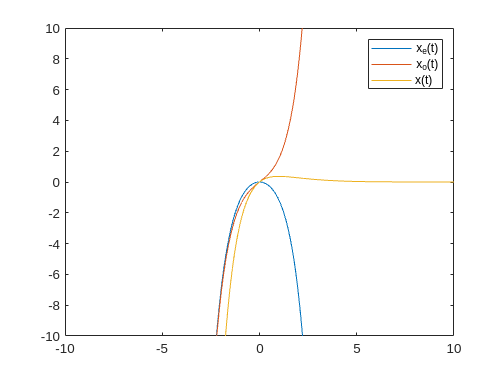



fplot(x_e,[-10 10])
hold on
fplot(x_o,[-10 10])
fplot(x,[-10 10])
hold off
ylim([-10 10])
legend("x_{e}(t)","x_{o}(t)","x(t)")

## RMS de funcion seno

syms t

T = 2*pi

T = 6.2832

%Señal
x = sin(t)

$$x = \sin\left(t\right)$$

%Energía
E = int(x^2,[0 T])

$$E = \pi$$

%Potencia
P = E/(T)

$$P = \frac{1}{2}$$

%RMS
RMS = sqrt(P)

$$RMS = \frac{\sqrt{2}}{2}$$

var = vpa(RMS)

$$var = 0.70710678118654752440084436210485$$